# Show Productive Structure Demo

Show the Productive Structure Info and the Productive Diagrams  

#### Read Data Model

file="D:\Documents\Proyectos\TaesLab\Examples\rorc\rorc_model.json";
data=ReadDataModel(file);

#### Get the Productive Structure Tables

res=ProductiveStructure(data,'Show',true);

Flows Definition Table

  Id Key   From    To      Type      
——————————————————————————————————————
   1 B1    BLR_P1  TRB_F1  INTERNAL  
   2 B2    TRB_F1  IHE_F1  INTERNAL  
   3 B3    IHE_F1  CND_F1  INTERNAL  
   4 B4    CND_F1  PMP_P1  INTERNAL  
   5 B5    PMP_P1  IHE_P1  INTERNAL  
   6 B6    IHE_P1  BLR_P1  INTERNAL  
   7 QBLR  ENV_R1  BLR_F1  RESOURCE  
   8 WP    TRB_P1  PMP_F1  INTERNAL  
   9 WN    TRB_P1  ENV_O1  OUTPUT    
  10 QCND  CND_P1  ENV_W1  WASTE     


Productive Groups Definition Table

  Id Key     Definition  Type      
————————————————————————————————————
   1 BLR_F1  QBLR        FUEL      
   2 BLR_P1  B1-B6       PRODUCT   
   3 TRB_F1  B1-B2       FUEL      
   4 TRB_P1  WN+WP       PRODUCT   
   5 IHE_F1  B2-B3       FUEL      
   6 IHE_P1  B6-B5       PRODUCT   
   7 PMP_F1  WP          FUEL      
   8 PMP_P1  B5-B4       PRODUCT   
   9 CND_F1  B3-B4       FUEL      
  10 CND_P1  QCND        PRODUCT   
  11 ENV_R1  QBLR        RESOURCE  
  12 ENV_O1 

#### Show Flows Diagram

Get the the productive diagrams by means of `ProductiveDiagram` function, use the option `SaveAs `to save in excel format the adjacency tables, and shows the Flows Diagram (fat) using the `ShowGraph` function

dg=ProductiveDiagram(data,'SaveAs','rorc_pd.xlsx');

INFO: cStatusLogger. File rorc_pd.xlsx has been saved


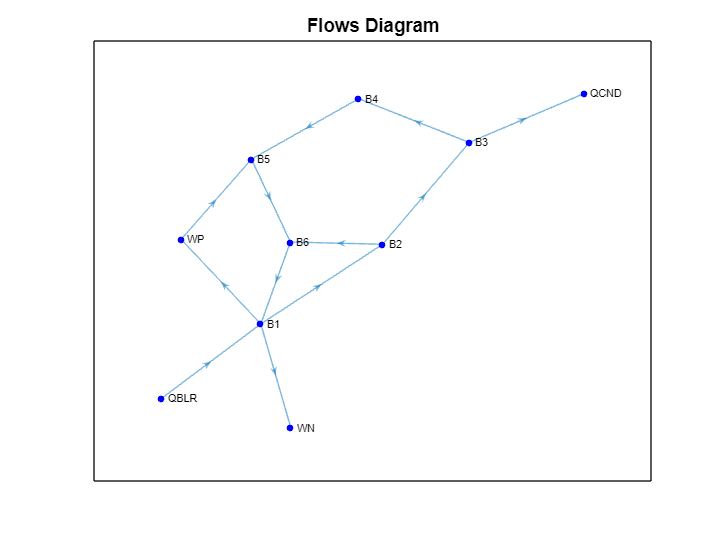

ShowGraph(dg,'Graph','fat');